**Calibration with the irradiation pattern provided by the manufacturer**

Search for the maximum angle with S = 1

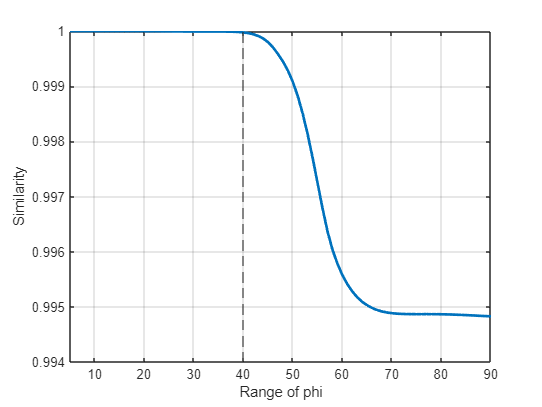

clc, clear, close

a_vals = 5:90;
S_vals = zeros(size(a_vals));
m_vals = zeros(size(a_vals));

g = @(m,phi) max(cosd(phi(:)),0).^m;   % lambertiana (no negativa)

for k = 1:numel(a_vals)
    a   = a_vals(k);
    phi = -a:a;

    y = arrayfun(@(p) irradiance(p,'poly'), phi);
    ny = norm(y);
    if ny==0, S_vals(k)=NaN; m_vals(k)=NaN; continue; end

    Sfun = @(m) ( y(:)'*g(m,phi) ) / ( ny * norm(g(m,phi)) );  % cosine similarity
    [m_opt, ~] = fminbnd(@(m) -Sfun(m), 0, 50);
    S_vals(k) = Sfun(m_opt);
    m_vals(k) = m_opt;
end

tol = 10^(-4.5);  % tolerancia para "S = 1"
idx = find(1 - S_vals < tol, 1, 'last');


figure
plot(a_vals,S_vals,'LineWidth',2)
xline(a_vals(idx),'--')
ylabel('Similarity')
xlabel('Range of phi')
xlim([a_vals(1) a_vals(end)])
grid on

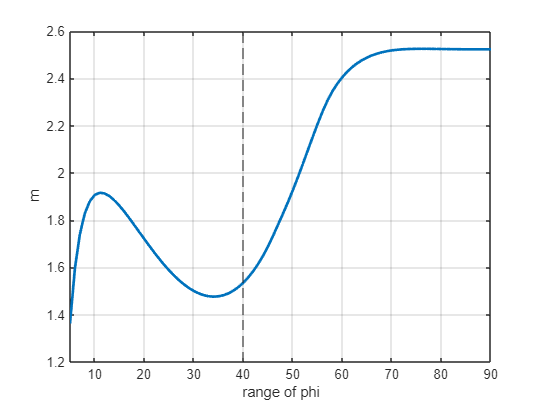


figure
plot(a_vals,m_vals,'LineWidth',2)
ylabel('m')
xlabel('range of phi')
xline(a_vals(idx),'--')
xlim([a_vals(1) a_vals(end)])
grid on

For an specifical range

phi = -40:40;
R_datasheet = arrayfun(@(p) irradiance(p,'poly'), phi);
x = phi;
y = R_datasheet(:);
y = y / norm(y); % Norm L2 -> sum(y.^2)=1 

% Cosine similarity
S = @(m) ( y' * ( cosd(x(:)).^m / (norm(cosd(x(:)).^m)) ) );

% Maximiza S (equivalente a minimizar -S)
[m_opt, ~] = fminbnd(@(m) -S(m), 0, 20);

S(m_opt)

ans = 1.0000

m_opt

m_opt = 1.5355

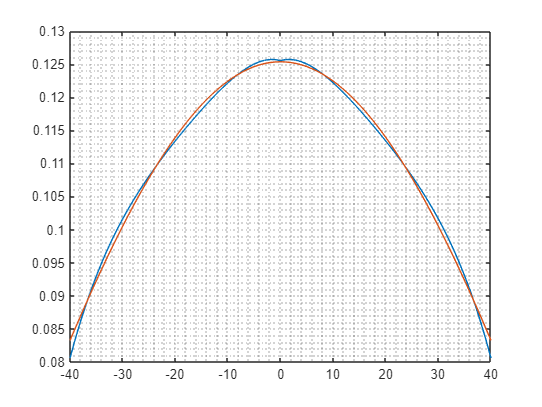

R_Lam = max(cosd(x),0).^m_opt;
R_Lam_norm = R_Lam / norm(R_Lam);

figure
plot(x,y)
hold on
plot(x,R_Lam_norm)
hold off
grid minor

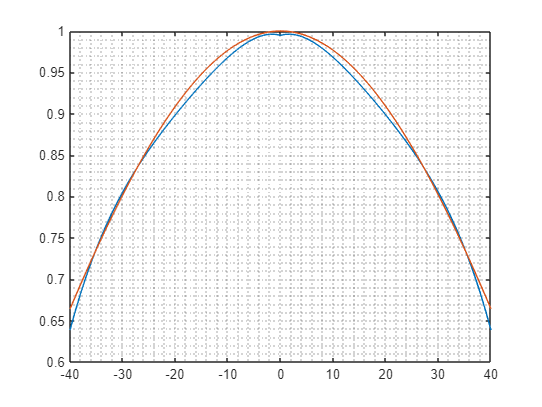



figure
plot(x,R_datasheet)
hold on
plot(x,R_Lam)
grid minor

Comparison between profiles

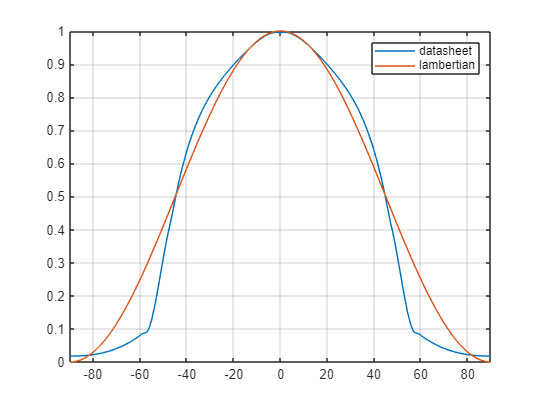

phi = -90:90;
R_datasheet = arrayfun(@(p) irradiance(p,'poly'), phi);

m_opt = 2;
R_Lam = max(cosd(phi),0).^m_opt;
R_Lam_norm = R_Lam / norm(R_Lam);


figure
plot(phi,R_datasheet)
hold on
plot(phi,R_Lam)
hold off
legend('datasheet','lambertian')
grid on
xaxis([-90 90])